# Cálculo de $\pi$

**Primer método **%Fórmula de Leibniz


$$\frac{\pi}{4}=1-\frac{1}{3}+\frac{1}{5}-\frac{1}{7}+\frac{1}{9}-\frac{1}{11}+...$$


Número fijo de iteraciones

n=9;
suma=1;
for i=1:1:100000
    suma= suma + (1/((2*i)+1))*(-1)^i; 
end
piA1=4*suma

piA1 = 3.1416

elem=zeros(1,n);
elem(1)=1;
for j=2:n
    elem(j)=(1/(2*j-1)*(-1)^(j+1));
end
%piA2=sum(elem)*4;

Numero de variable de iteraciones

format long
pi;
sf = 6;
m= sf-1;
TOL= 1*10^-m; %5*10^-m
piAp = 0; %previa aproximacion
piA = 1;
i=1;

while abs((piA-piAp)/piA)> TOL
    piAp=piA;
    piA=piAp+ ((-1)^i)/((2*i)+1);
    i=i+1;
end

abs((piA-piAp)/piA)

ans =      9.999867886711085e-06


i

i =        63663


piA*4

ans =    3.141608361300682


### Montecarlo

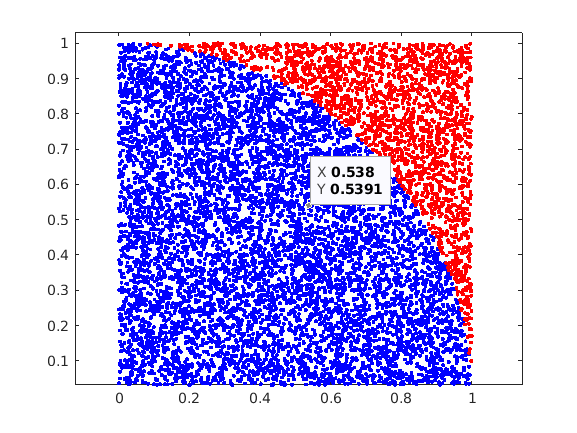

n=10000;
x=rand(1,n);
y=rand(1,n);
r=x.^2 + y.^2;
inside= r<=1;
outside= r>1;
plot(x(inside),y(inside),'b.');
axis equal;
hold on;
plot(x(outside), y(outside),'r.');


p=sum(inside)/n

p =    0.789300000000000


piAMC=4*p

piAMC =    3.157200000000000


q=1-p;
sd=sqrt(p*q);
alfa=.05;
z=norminv(1-alfa/2);
se= sd/sqrt(n);
fprintf('%7.4f +- %6.4f\n',4*p,4*z*se)

 3.1572 +- 0.0320
